# Cviceni 7 

## Priklad 1

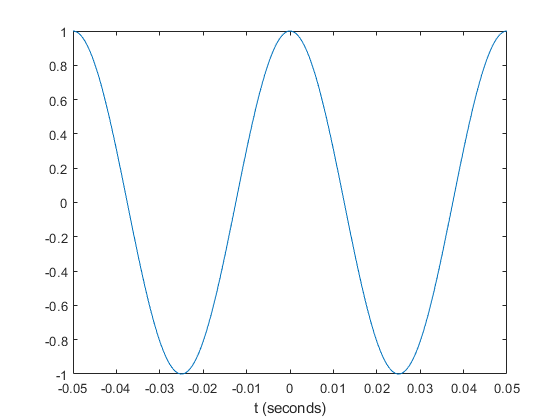

f = 20;  % Hz
tmin = -0.05;
tmax = 0.05;
t = linspace(tmin, tmax, 400);
x_c = cos(2*pi*f * t);

figure,
plot(t,x_c)
xlabel('t (seconds)');

### Vzorkovani s frekvenci 1/400

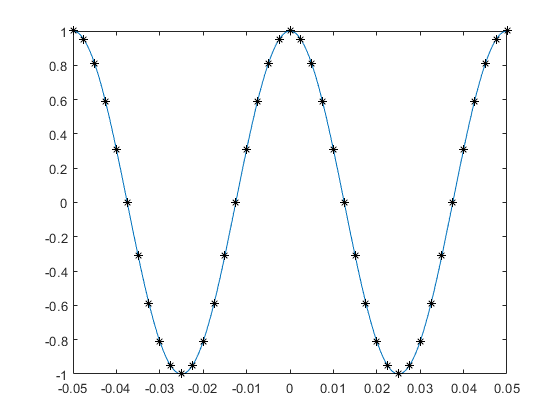

T = 1/400;
nmin = ceil(tmin / T);
nmax = floor(tmax / T);
n = nmin:nmax;
x1 = cos(2*pi*f * n*T);

figure,
plot(t, x_c)
hold on
plot(n*T, x1, '*k')
hold off

### Vzorkovani s frekvenci 1/120

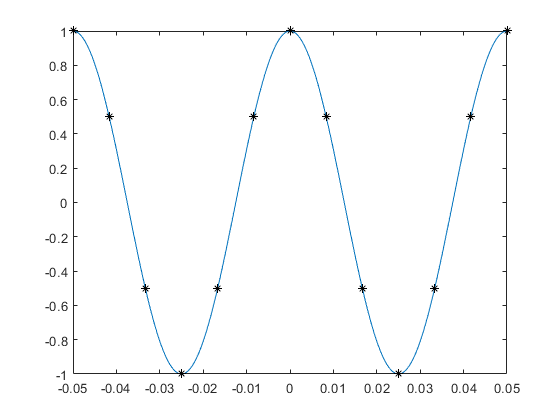

T = 1/120;
nmin = ceil(tmin / T);
nmax = floor(tmax / T);
n = nmin:nmax;
x1 = cos(2*pi*f * n*T);

figure,
plot(t, x_c)
hold on
plot(n*T, x1, '*k')
hold off

### Vzorkovani s frekvenci 1/40

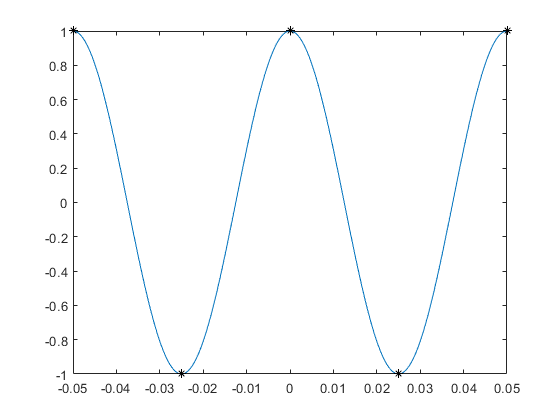

T = 1/40;
nmin = ceil(tmin / T);
nmax = floor(tmax / T);
n = nmin:nmax;
x1 = cos(2*pi*f * n*T);

figure,
plot(t, x_c)
hold on
plot(n*T, x1, '*k')
hold off

### Vzorkovani s frekvenci 1/30

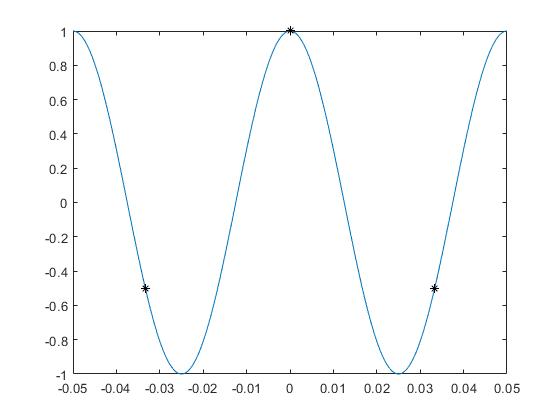

T = 1/30;
nmin = ceil(tmin / T);
nmax = floor(tmax / T);
n = nmin:nmax;
x1 = cos(2*pi*f * n*T);

figure,
plot(t, x_c)
hold on
plot(n*T, x1, '*k')
hold off

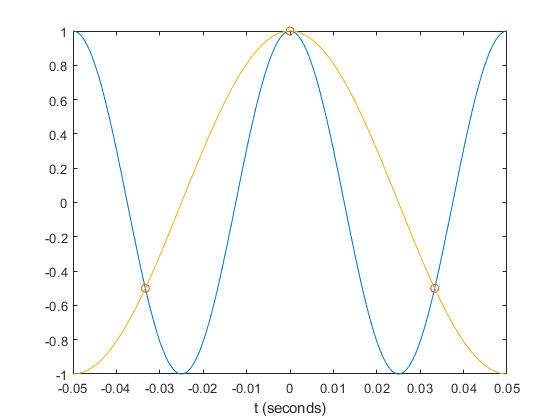

f = 20;  % Hz
tmin = -0.05;
tmax = 0.05;
t = linspace(tmin, tmax, 400);
x_c = cos(2*pi*f * t);

figure,
plot(t,x_c)
xlabel('t (seconds)');

T = 1/30;
x_c = cos(2*pi*10 * t);
nmin = ceil(tmin / T);
nmax = floor(tmax / T);
n = nmin:nmax;
x1 = cos(2*pi*f * n*T);


hold on
plot(n*T, x1, 'o')
plot(t, x_c)
hold off

### Funkce prevedena do frekvencni domeny

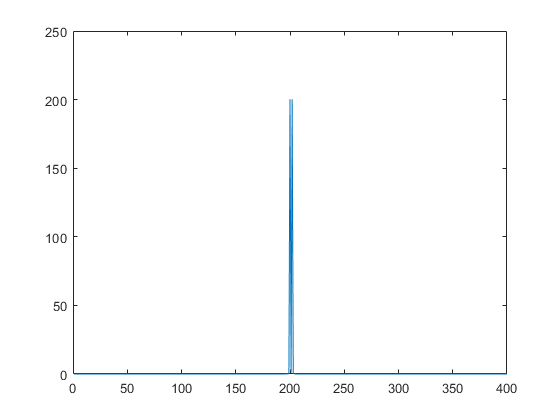

F = fft(x_c);
F_sp = abs(F);

figure,
plot(fftshift(F_sp));

## Diracuv pulz

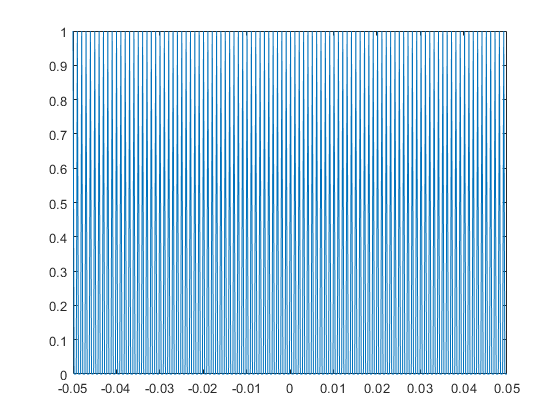

f = 4;  
%f = 10;
tmin = -0.05;
tmax = 0.05;
t = linspace(tmin, tmax, 400);

x1 = zeros([1,400]);
x1(1:f:400) = 1;

figure,
plot(t, x1);

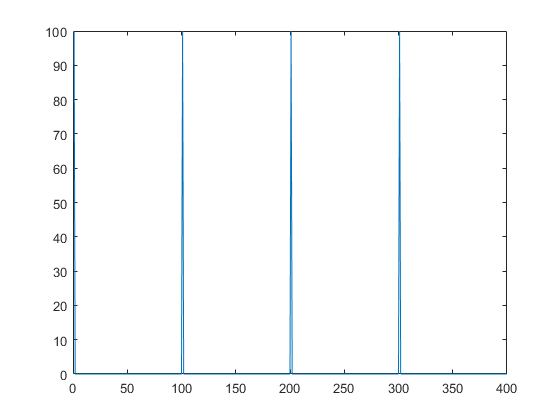

F = fft(x1);
F_sp = abs(F);

figure,
plot(fftshift(F_sp));

## Priklad 2 - Časový alias

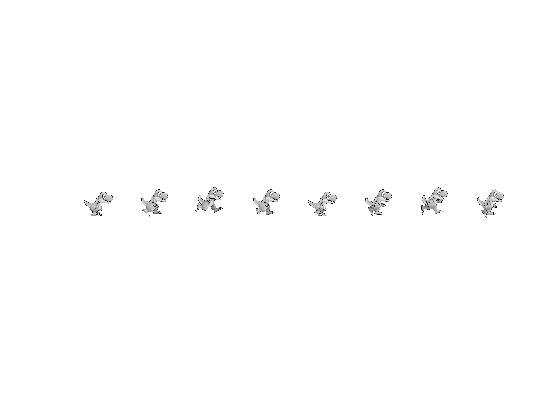

i1 = rgb2gray(imread('Run1.png'));
i2 = rgb2gray(imread('Run2.png'));
i3 = rgb2gray(imread('Run3.png'));
i4 = rgb2gray(imread('Run4.png'));
i5 = rgb2gray(imread('Run5.png'));
i6 = rgb2gray(imread('Run6.png'));
i7 = rgb2gray(imread('Run7.png'));
i8 = rgb2gray(imread('Run8.png'));

I = [];
I = uint8(I);

% vytvoreni sekvence
for  i = 1 : 8 : 500    
    I(:,:,i) = i1;
    I(:,:,i+1) = i2;
    I(:,:,i+2) = i3;
    I(:,:,i+3) = i4;
    I(:,:,i+4) = i5;
    I(:,:,i+5) = i6;
    I(:,:,i+6) = i7;
    I(:,:,i+7) = i8;
end

figure,
subplot(1,8,1), imshow(i1);
subplot(1,8,2), imshow(i2);
subplot(1,8,3), imshow(i3);
subplot(1,8,4), imshow(i4);
subplot(1,8,5), imshow(i5);
subplot(1,8,6), imshow(i6);
subplot(1,8,7), imshow(i7);
subplot(1,8,8), imshow(i8);

### krok 1

figure,
for i = 1:size(I,3)
   imshow(I(:,:,i))
    pause(.1);
end

### krok 4

figure,
for i = 3:4:size(I,3)
   imshow(I(:,:,i))
    pause(.1);
end

### krok 7

figure,
for i = 1:6:size(I,3)
    imshow(I(:,:,i))
    pause(.1);
end

### krok 10

figure,
for i = 1:8:size(I,3)
    imshow(I(:,:,i))
    pause(.1);
end

### krok 11

figure,
for i = 1:9:size(I,3)
    imshow(I(:,:,i))
    pause(.1);
end

## Priklad 3 - šachovnice

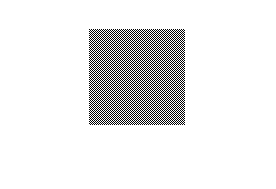

% generovani obrazku sachovnice
sachovnice = mat2gray(checkerboard(1,48,48) > 0.5);
figure,
imshow(sachovnice);

### Vzorkovani s krokem 1/6

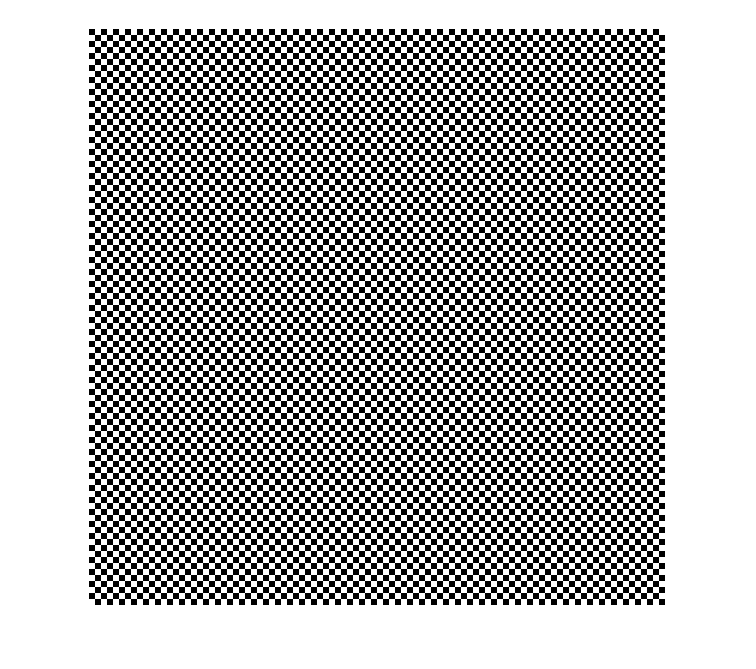

s2 = imresize(sachovnice,6,'nearest');
figure,
imshow(s2);

### Vzorkovani s krokem 1/16

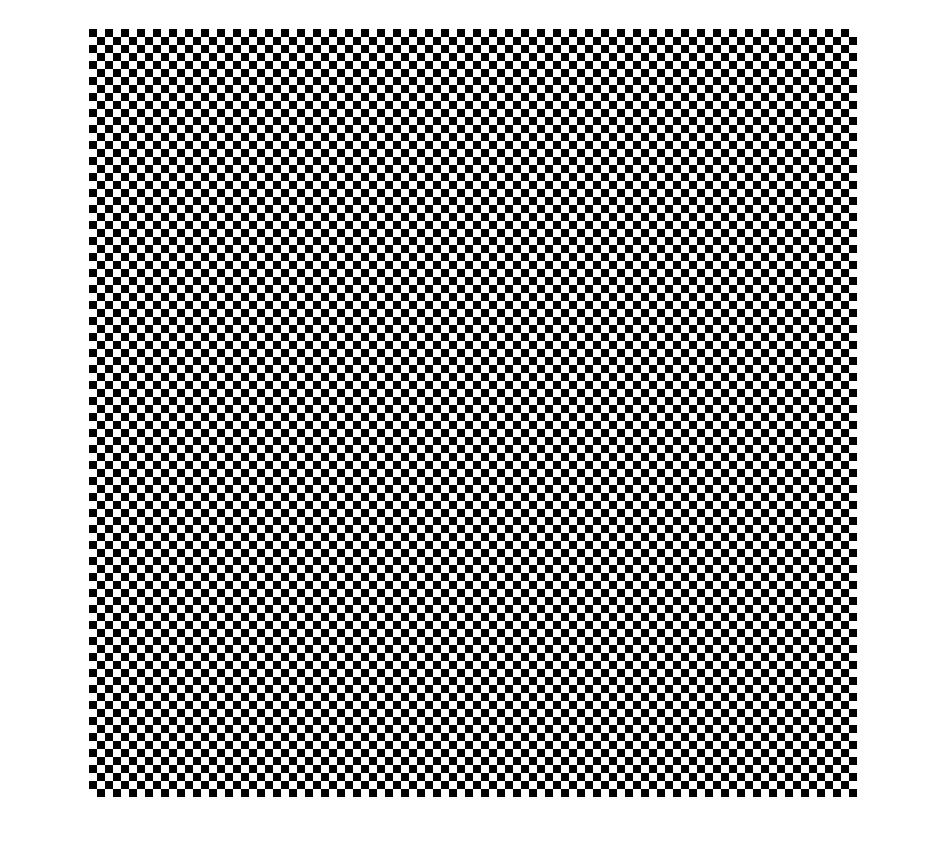

s3 = imresize(sachovnice,16,'nearest');
figure,
imshow(s3);

### Vzorkovani s krokem 1/0.9174

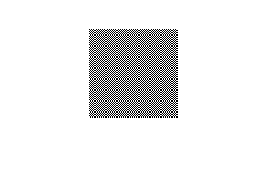

s4 = imresize(sachovnice,0.9174,'nearest');
figure,
imshow(s4);

### Vzorkovani s krokem 1/0.4798

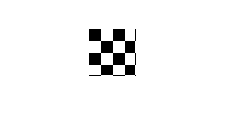

s5 = imresize(sachovnice,0.4798,'nearest');
figure,
imshow(s5);

### Vzorkovani s krokem 1/0.5

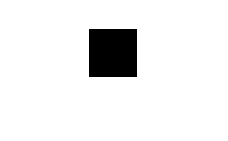

s6 = imresize(sachovnice,0.5,'nearest');
figure,
imshow(s6);

## Priklad 4 - moire

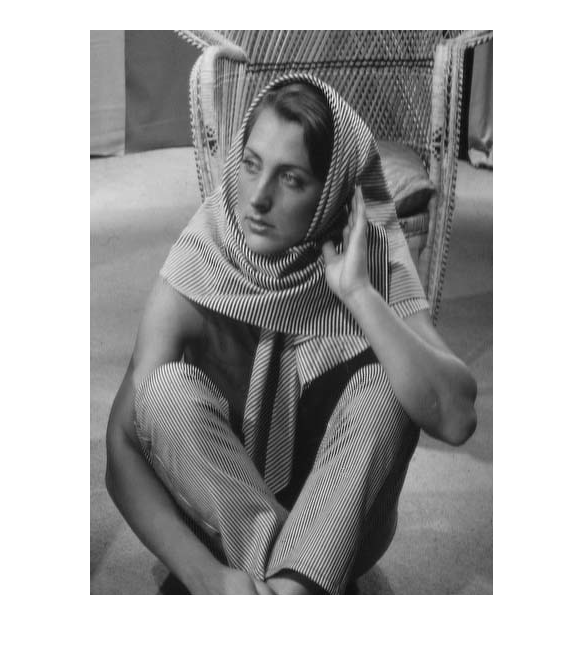

I = rgb2gray(imread('alias4.png'));
figure,
imshow(I);

### Mensi vzorkovaci frekvence

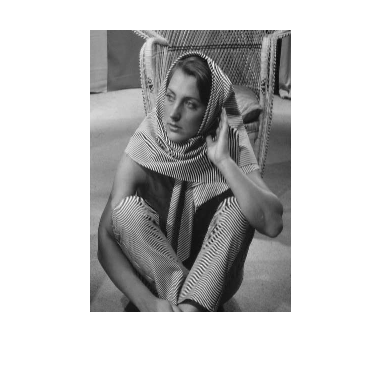

I05 = I(1:2:end,1:2:end);
figure,
imshow(I05);

#### Zvetseni vzorkovaneho obrazku

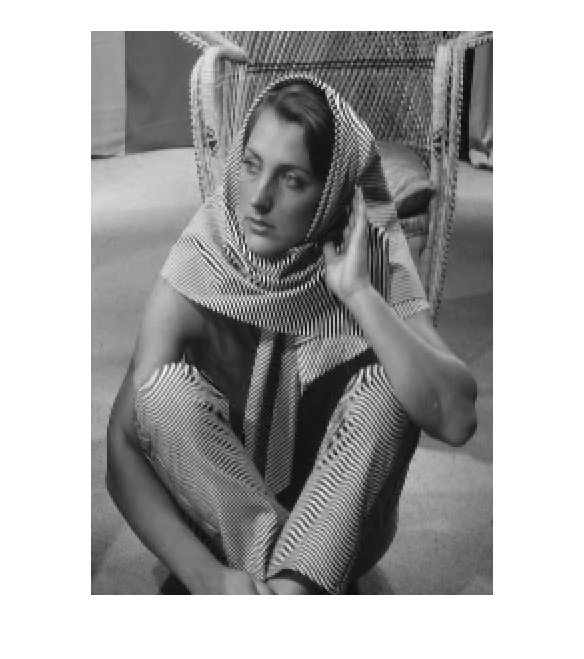

I1 = uint8(zeros(size(I)));
I1(1:2:end,1:2:end)=I05;
I1(1:2:end,2:2:end)=I05;
I1(2:2:end,2:2:end)=I05;
I1(2:2:end,1:2:end)=I05;

figure,imshow(I1);

### Rozmazani obrazku pred vzorkovanim (mene detailu v obrazku)

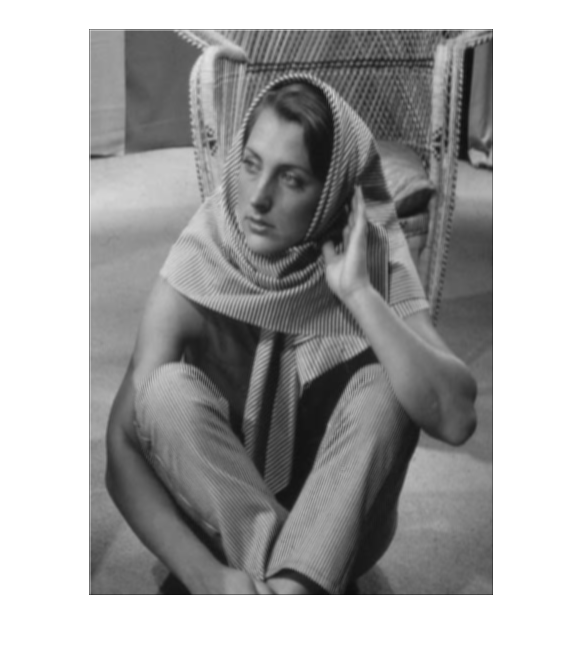

w = 1/9 * [1 1 1; 
           1 1 1; 
           1 1 1];
Iblur = imfilter(I,w,'corr','same');
figure,
imshow(Iblur);

### Vzorkovani rozmazaneho obrazku

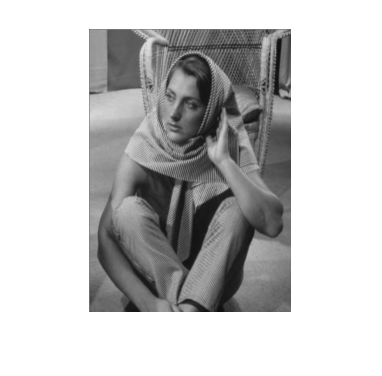

 I05blur = Iblur(1:2:end,1:2:end);
 figure,
imshow(I05blur);

#### Zvetseni vzorkovaneho obrazku

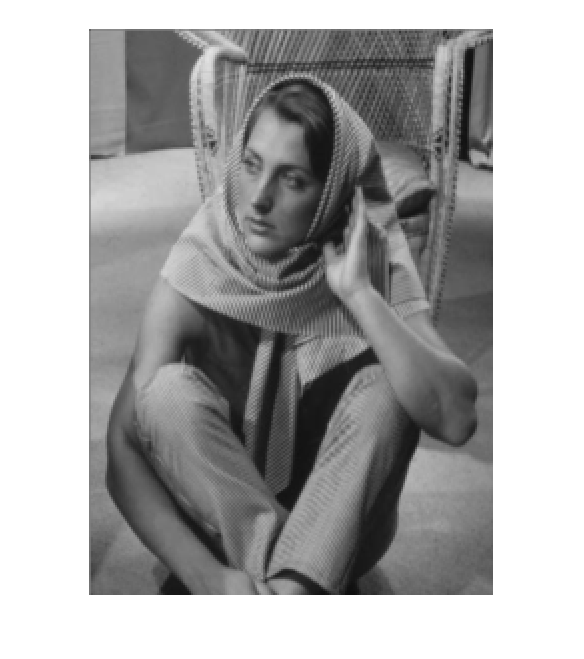

I1blur = uint8(zeros(size(I)));
I1blur(1:2:end,1:2:end)=I05blur;
I1blur(1:2:end,2:2:end)=I05blur;
I1blur(2:2:end,2:2:end)=I05blur;
I1blur(2:2:end,1:2:end)=I05blur;
figure,
imshow(I1blur);

### Srovnani obrazku

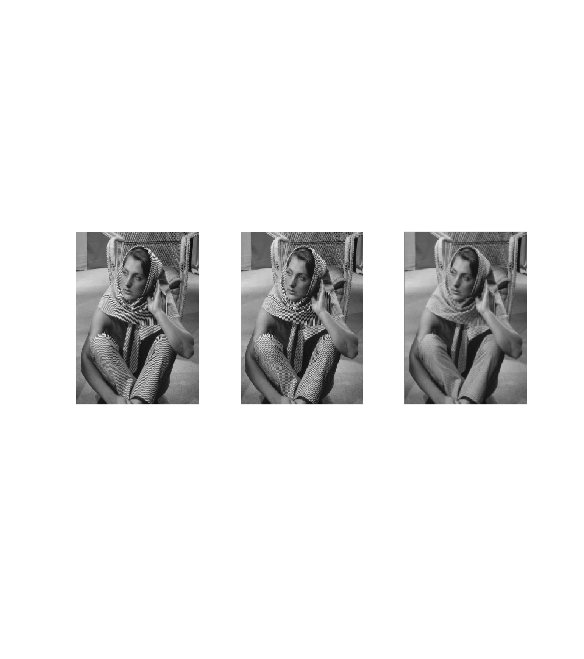

subplot(1,3,1), imshow(I);
subplot(1,3,2), imshow(I1);
subplot(1,3,3), imshow(I1blur);

## Supersampling

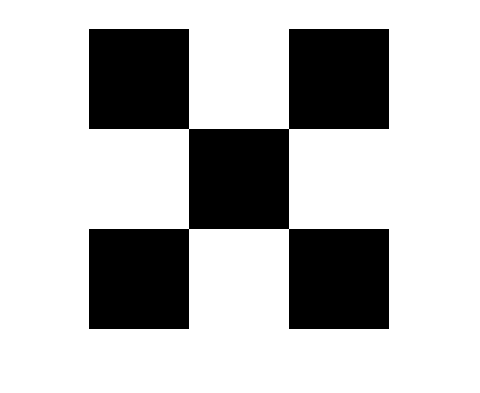

C = imread('sachovnice.png');
figure,
imshow(C);

### Vzorkovani

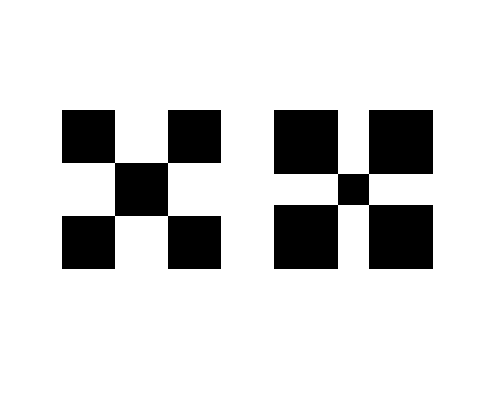

CC = imresize(C, [5 5], 'nearest');
CCC = imresize(CC, [300 300], 'nearest');

subplot(1,2,1), imshow(C);
subplot(1,2,2), imshow(CCC);

### Pravidelne vzorkovani

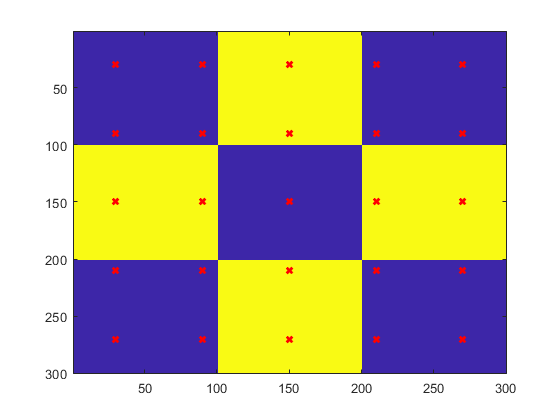

figure,
[ p_g, v_g ] = Sampling_Grid( C, 20, true );

### Roztresene vzorkovani

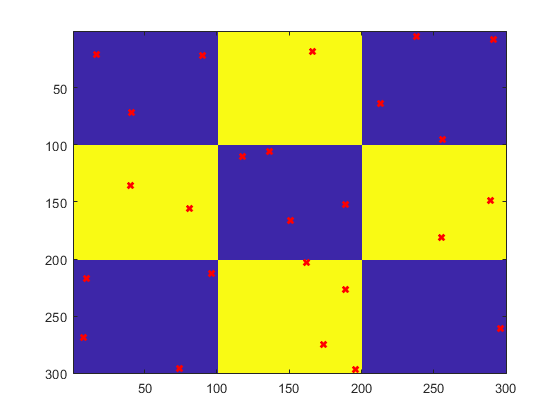

figure,
[ p_j, v_j ] = Sampling_Jittered( C, 20, true );

## Príklad down sampling na m1 x n1 velikost

C = imread('sachovnice.png');
figure,
imshow(C);

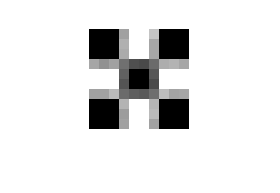


[m,n] = size(C);

%nova velikost 5x5
m1 = 10;
n1 = 10;

% velikosti oblasti:
mm = floor(m/m1);
nn = floor(n/n1);

k = 100;

vysl = uint8(zeros(m1,n1));
% vytvorim oblast a z ni nahodne vyberu k vzorku a z nich vezmu prumer
for i = 1:m1
    for j = 1:n1
        oblast = C((i-1)*mm + 1 : i*mm, (j-1)*nn + 1 : j*nn);
        %imshow(oblast);
        oblast = oblast(:);
        permutace = randperm(size(oblast,1));
        oblast = oblast(permutace);
        vysl(i,j) = mean(oblast(1:k));
    end
end

figure,
imshow(imresize(vysl,10,'nearest'));

## UKOL 1

Upravte predchozi priklad tak, aby se misto nahodnych vzorku z oblasti vybraly vzorky v pravidelne mrizce velikosti k x k. Uprava se tyka radku 238 - 243. Vyzkousejte vysledek i na jinych obrazcich (pro jednoduchost ctvercovych).

## UKOL 2

Upravte predchozi priklad tak, aby se misto nahodnych vzorku z oblasti vybraly vzorky dle algoritmu n- vezi. Uprava se tyka radku 238 - 243. Vyzkousejte vysledek i na jinych obrazcich (pro jednoduchost ctvercovych).

## Permutace diagonaly matice nxn

n=3;
M = eye(n);
     
permutace = perms(1:n);

pocet_permutaci = size(permutace,1);

for i = 1 : pocet_permutaci
    disp(M(:,permutace(i,:)));
end

     0     0     1
     0     1     0
     1     0     0

     0     1     0
     0     0     1
     1     0     0

     0     0     1
     1     0     0
     0     1     0

     0     1     0
     1     0     0
     0     0     1

     1     0     0
     0     0     1
     0     1     0

     1     0     0
     0     1     0
     0     0     1

